Lab 7

Event selection optimization You and your lab partner should pick *different* pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).

IM USING HIGH PT

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

- Make a stacked histogram plot for the feature variable: mass (a regular histogram)

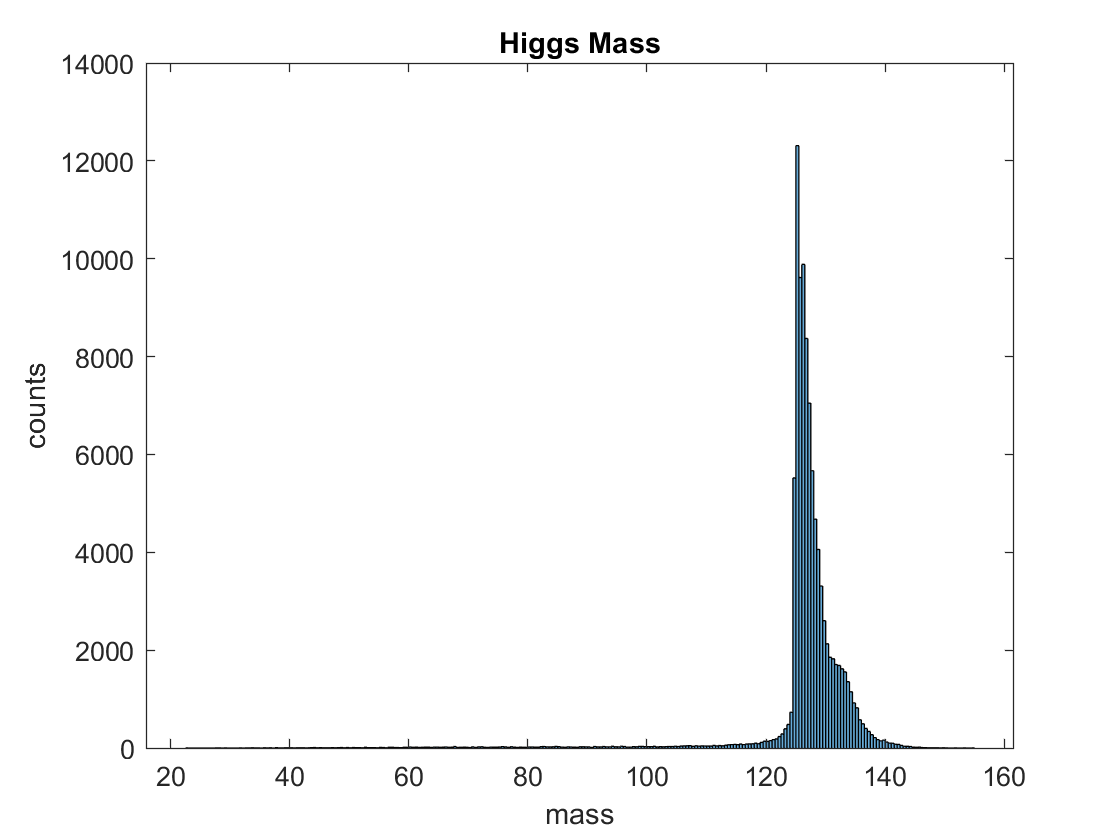

histogram(higgs(4,:));
title('Higgs Mass')
xlabel('mass')
ylabel('counts')

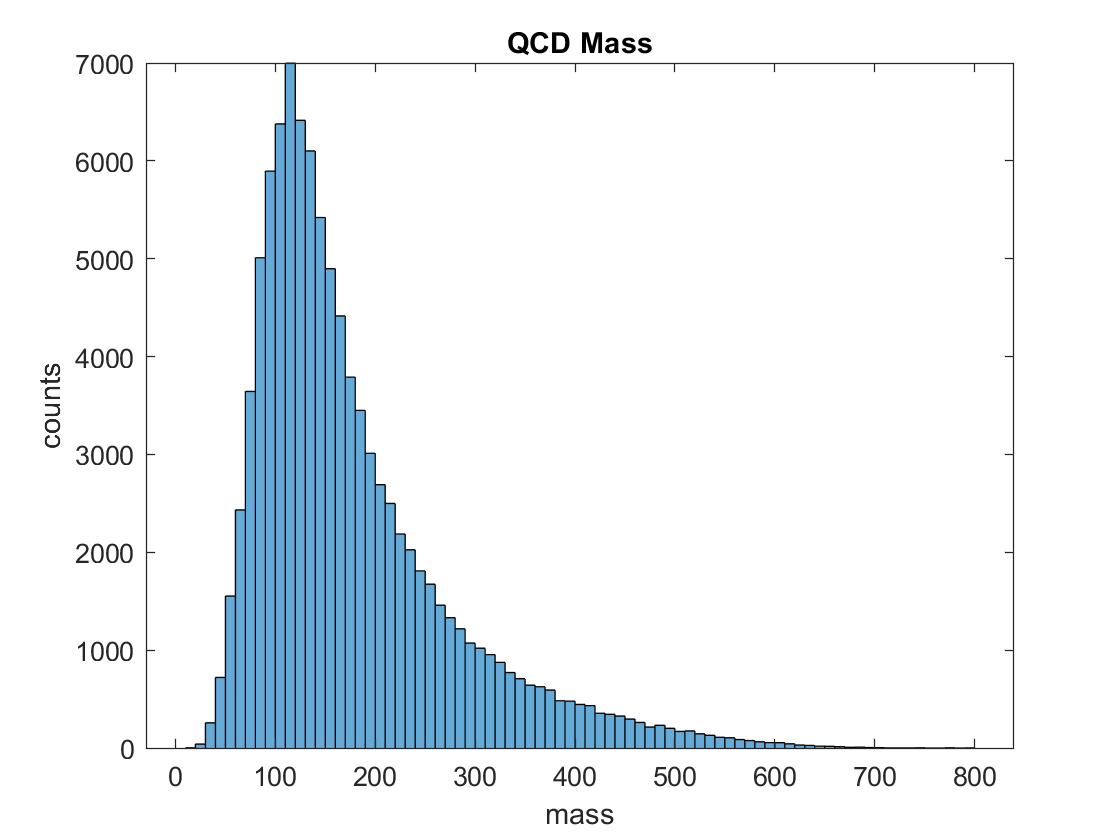


histogram(qcd(4,:));
title('QCD Mass')
xlabel('mass')
ylabel('counts')


Nhiggs = 50;
Nqcd = 2000;

- Evaluate expected significance without any event selection.

- Use Poisson statistics for significance calculation

poiss = makedist('Poisson','lambda',2000);
signal = 2050;

pr = cdf(poiss,signal)

pr = 0.8704

sigma = norminv(pr)

sigma = 1.1282

- Compare your number of NHiggs/(√NQCD)NHiggs/(NQCD). If they are equivalent, explain your findings.

- --Number of events is a poisson distribution with lambda Nhiggs or Nqcd--

- significance of 2050 in a poisson 2000 dist

ratio = Nhiggs/(sqrt(Nqcd))

ratio = 1.1180

-- sigma??? :)

- Identify mass cuts to optimize the expected significance.

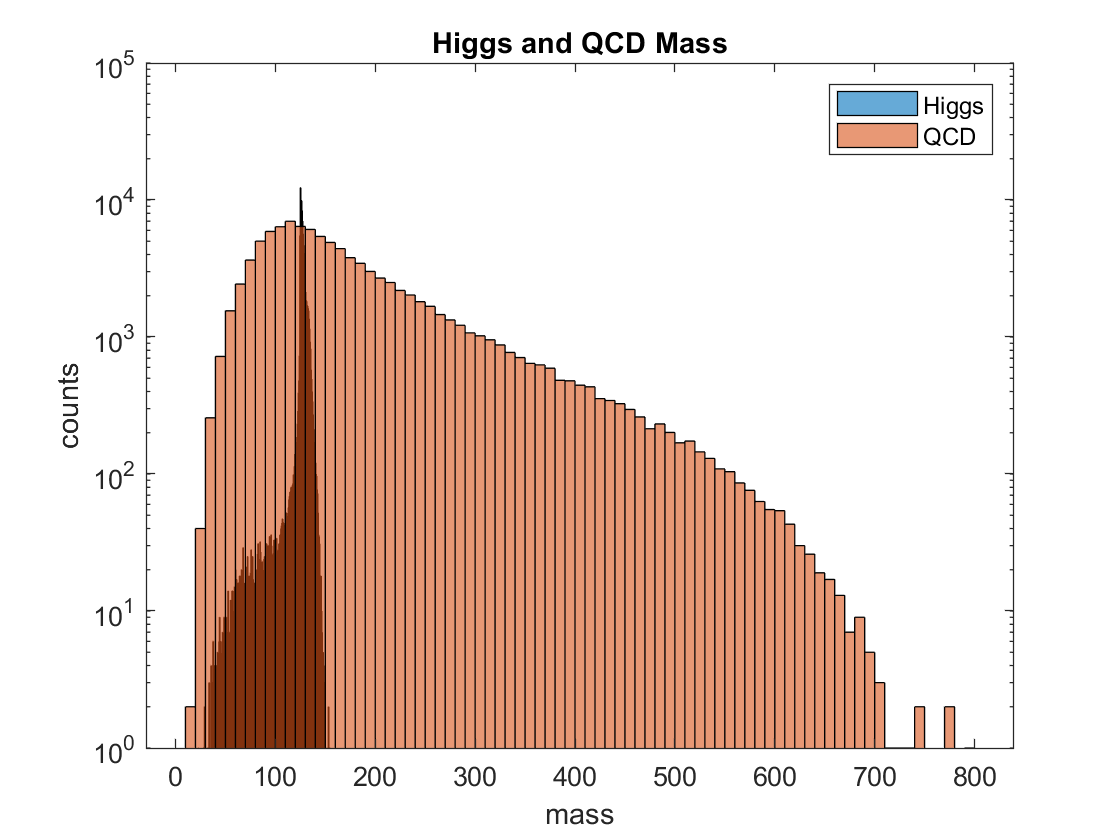

histogram(higgs(4,:));
hold on
histogram(qcd(4,:));
set(gca,'Yscale','log')
title('Higgs and QCD Mass')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

The Higgs data runs from ~(25 to 175) so we can cut out any background before and after that.

l = length(higgs(4,:));
hcount = zeros(1,l);

for i = 1:l
    if (100 < higgs(4,i)) && (higgs(4,i) < 140)
        hcount(i) = 1;
    else
        hcount(i) = 0;
    end
end

Nhiggs = sum(hcount)*50/l

Nhiggs = 48.6715


bcount = zeros(1,l);

for i = 1:l
    if (100 < qcd(4,i)) && (qcd(4,i) < 140)
        bcount(i) = 1;
    else
        bcount(i) = 0;
    end
end

Nqcd = sum(bcount)*2000/l

Nqcd = 517.8000


significance = Nhiggs/(sqrt(Nqcd))

significance = 2.1389

<FIND SIGNIFICANCE AND COMPARE>

-- for this, use the ratio!!!! Isolate stuff then find Nhiggs and Nqcd :)))))

j = 100:1:120;
k = 121:1:140;
J = length(j);
K = length(k);


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M = zeros(1,14);

M(4) = max(sigs,[],'all');
[A,B] = max(sigs,[],"all",'linear')

A = 3.3696

B = 210

%%j is row, k is column 21x20
B/21

ans = 10

sigs(21,10)

ans = 3.3696

j(21)

ans = 120

k(10)

ans = 130

So the best interval resulting in the largest significance is 120<mass<130

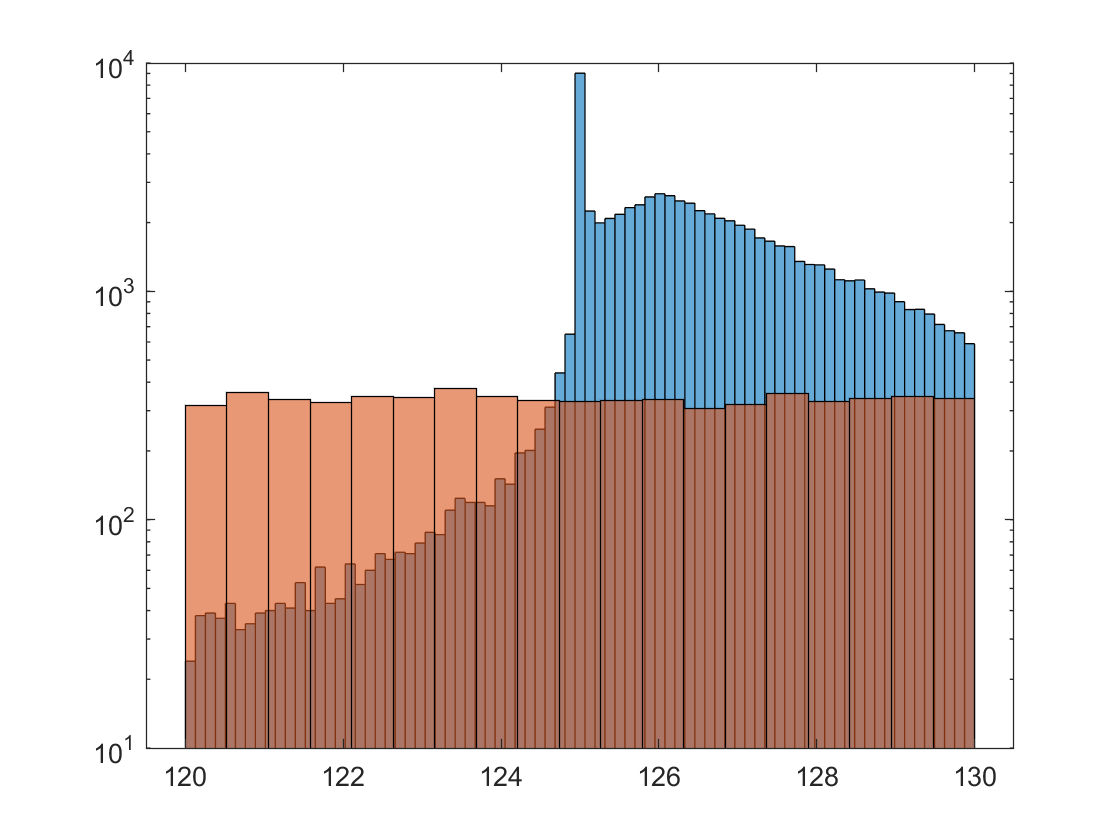

histogram(higgs(4,:),'BinLimits',[120,130]);
hold on
histogram(qcd(4,:),'BinLimits',[120,130]);
set(gca,'Yscale','log')
hold off

<SYSTEMATIC CUTS (loop)>

-- loopify the cuts 

- Try different mass cuts systematically

- Evaluate expeced significance for each set of mass cuts

- Identify the set of the mass cuts which give you the highest significance.

Make stacked histogram plots for the rest of features

%pt
histogram(higgs(1,:));
hold on
histogram(qcd(1,:));
set(gca,'Yscale','log')
title('Higgs and QCD pt')
xlabel('pt')
ylabel('counts')
legend('Higgs','QCD')
hold off

%eta
histogram(higgs(2,:));
hold on
histogram(qcd(2,:));
set(gca,'Yscale','log')
title('Higgs and QCD eta')
xlabel('eta')
ylabel('counts')
legend('Higgs','QCD')
hold off

phi
histogram(higgs(3,:));
hold on
histogram(qcd(3,:));
set(gca,'Yscale','log')
title('Higgs and QCD phi')
xlabel('phi')
ylabel('counts')
legend('Higgs','QCD')
hold off

%ee2
histogram(higgs(5,:));
hold on
histogram(qcd(5,:));
set(gca,'Yscale','log')
title('Higgs and QCD ee2')
xlabel('ee2')

ans = 4.0654

ylabel('counts')

A = 4.0654

B = 836

legend('Higgs','QCD')
hold off

ans = 16.3922


%ee3

ans = 20

histogram(higgs(6,:));
hold on

ans = 4.0654

histogram(qcd(6,:));

ans = 107.6000

set(gca,'Yscale','log')

ans = 127.4000

title('Higgs and QCD ee3')

ans = 0.1900

xlabel('ee3')

ans = 0.6700

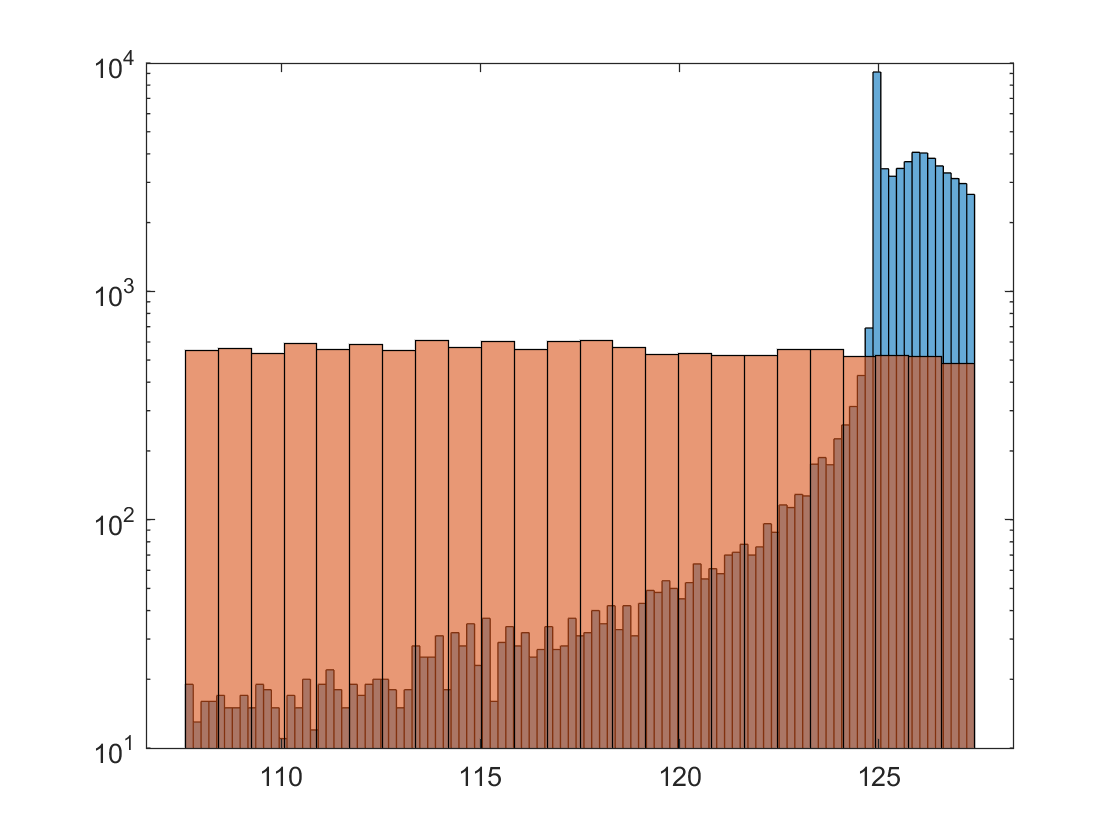

ylabel('counts')
legend('Higgs','QCD')
hold off

%d2
histogram(higgs(7,:));

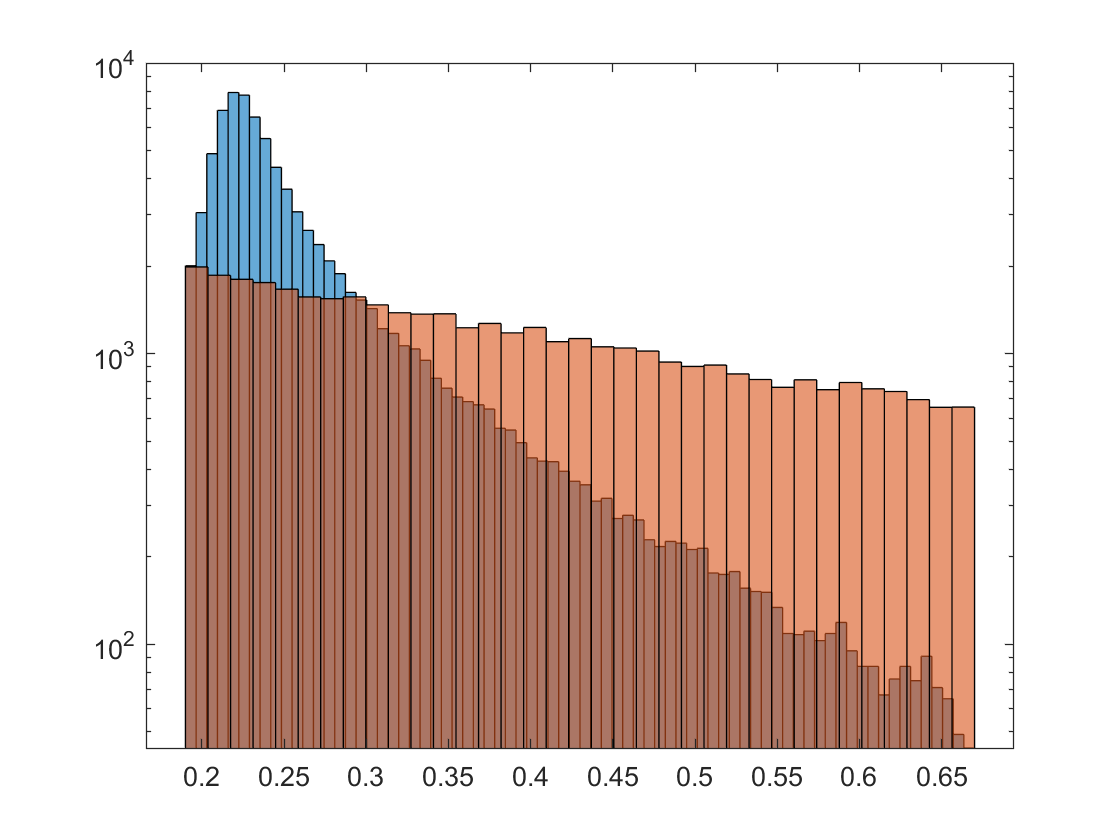

hold on
histogram(qcd(7,:));
set(gca,'Yscale','log')
title('Higgs and QCD d2')
xlabel('d2')
ylabel('counts')

legend('Higgs','QCD')
hold off

%angularity
histogram(higgs(8,:));
hold on
histogram(qcd(8,:));
set(gca,'Yscale','log')
title('Higgs and QCD angularity')
xlabel('angularity')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t1
histogram(higgs(9,:));
hold on
histogram(qcd(9,:));
set(gca,'Yscale','log')
title('Higgs and QCD t1')
xlabel('t1')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t2
histogram(higgs(10,:));
hold on
histogram(qcd(10,:));
set(gca,'Yscale','log')
title('Higgs and QCD t2')
xlabel('t2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t3
histogram(higgs(11,:));
hold on
histogram(qcd(11,:));
set(gca,'Yscale','log')
title('Higgs and QCD t3')
xlabel('t3')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t21
histogram(higgs(12,:));
hold on
histogram(qcd(12,:));
set(gca,'Yscale','log')
title('Higgs and QCD t21')
xlabel('t21')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t32
histogram(higgs(13,:));
hold on
histogram(qcd(13,:));
set(gca,'Yscale','log')
title('Higgs and QCD t32')
xlabel('t32')
ylabel('counts')
legend('Higgs','QCD')
hold off

%KtDeltaR
histogram(higgs(14,:));
hold on
histogram(qcd(14,:));
set(gca,'Yscale','log')
title('Higgs and QCD KtDeltaR')
xlabel('KtDeltaR')
ylabel('counts')
legend('Higgs','QCD')
hold off

- Set A of plots without any event selection

- Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)

%pt
j = 1000:10:1100;
k = 1110:10:1200;
J = length(j);
K = length(k);
r = 1;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%eta
j = -2:0.1:0;
k = 0.1:0.1:2;
J = length(j);
K = length(k);
r = 2;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%phi
j = -3:0.1:0;
k = 0.1:0.1:3;
J = length(j);
K = length(k);
r = 3;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%ee2
j = 0:0.01:0.22;
k = 0.23:0.01:0.45;
J = length(j);
K = length(k);
r = 5;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%ee3
j = 0:0.001:0.035;
k = 0.0351:0.001:0.07;
J = length(j);
K = length(k);
r = 6;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%d2
j = 0:0.5:50;
k = 50.5:0.5:100;
J = length(j);
K = length(k);
r = 7;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%angularity
j = 0:0.01:0.15;
k = 0.16:0.01:0.3;
J = length(j);
K = length(k);
r = 8;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%t1
j = 0.5:0.05:1.75;
k = 1.8:0.05:3;
J = length(j);
K = length(k);
r = 9;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%t2
j = 0:0.01:0.5;
k = 0.51:0.01:1;
J = length(j);
K = length(k);
r = 10;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%t3
j = 0:0.01:0.5;
k = 0.51:0.01:1;
J = length(j);
K = length(k);
r = 11;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%t21
j = 0:0.01:0.5;
k = 0.51:0.01:1;
J = length(j);
K = length(k);
r = 12;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%t32
j = 0:0.01:0.5;
k = 0.51:0.01:1;
J = length(j);
K = length(k);
r = 13;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all');

%KtDeltaR
j = 0:0.01:0.5;
k = 0.51:0.01:1;
J = length(j);
K = length(k);
r = 14;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M(r) = max(sigs,[],'all')

- Set B of plots with your optimal mass cuts

- Can you identify additional feature to further imrpove expected signifiance?

-     KtDeltaR is the next highest significance (~1.7)

Optimize event selections using multiple features (if necessary)

- Find a set of feature cuts which can help you to achieve the best significance.

j = 100:0.4:120;
k = 121:0.4:140.8;
J = length(j);
K = length(k);

q = 0:0.01:0.5;
s = 0.51:0.01:1;
Q = length(q);
S = length(s);



sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m)) && (q(n) < higgs(14,i)) && (higgs(14,i) < s(S-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m)) && (q(n) < qcd(14,p)) && (qcd(14,p) < s(S-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

max(sigs,[],'all')
[A,B] = max(sigs,[],"all",'linear')
%%j is row, k is column 21x20
B/51
%column 17
836 - 51*16
%row 20
sigs(20,17)
j(20)
k(17)
q(20)
s(17)

histogram(higgs(4,:),'BinLimits',[j(20),k(17)]);
hold on
histogram(qcd(4,:),'BinLimits',[j(20),k(17)]);
set(gca,'Yscale','log')
hold off

histogram(higgs(14,:),'BinLimits',[q(20),s(17)]);
hold on
histogram(qcd(14,:),'BinLimits',[q(20),s(17)]);
set(gca,'Yscale','log')
hold off

- Compare significance (before/after event selection) dervied in your pT samples to your lab partner. Describe your findings.